# BP 神经网络

#### 已知有11个样本，用前9个样本训练去预测最后2个样本，然后检验与最后2样本真实值的误差.

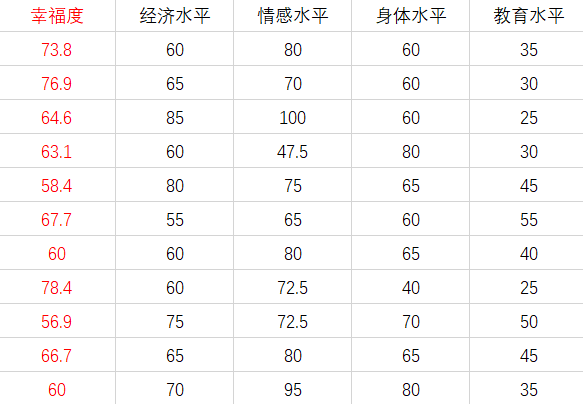

## 读取已知数据

clear
clc
input = [60	80	60	35
65	70	60	30
85	100	60	25
60	47.5	80	30
80	75	65	45
55	65	60	55
60	80	65	40
60	72.5	40	25
75	72.5	70	50
65	80	65	45
70	95	80	35
];
ouput = [73.8
76.9
64.6
63.1
58.4
67.7
60
78.4
56.9
66.7
60
];

## 设置训练数据和预测数据

input_train = input(1:9,:)';
output_train = ouput(1:9,:)';
input_test = input(10:11,:)';
output_test = ouput(10:11,:)';

## 设置结点

input_number=4; %经济水平、情感水平、身体水平、教育水平四个输入指标
hidden_number=5; %自定义
output_number=1; %幸福度一个输出指标

## 训练样本归一化

[input_n,input_ps] = mapminmax(input_train);
[output_n,output_ps] = mapminmax(output_train);

## 构造BP神经网络

net = newff(input_n,output_n,hidden_number,{'tansig','purelin'},'trainlm');
%purelin传递函数，采用梯度下降法训练
weight_1 = net.iw{1,1}; %输入层到隐藏层权值
cell_1 = net.b{1}; %隐藏层神经元阈值
weight_2 = net.lw{2,1}; %隐藏层到输出层权值
cell_2 = net.b{2}; %输出层神经元阈值

## 设置网络参数

net.trainParam.epochs = 1000; %训练次数
net.trainParam.lr = 0.01; %学习速率
net.trainParam.goal = 0.00001; %训练目标最小误差

## BP神经网络训练

net = train(net,input_n,output_n);

## 测试样本归一化

input_n_test = mapminmax('apply',input_test,input_ps);
%样本数据进行归一化

## BP神经网络预测

results = sim(net,input_n_test);
%使用已经训练的模型仿真

## 预测结果反归一化

simulation_test = mapminmax('reverse',results,output_ps);

## 真实值与预测值误差绘图

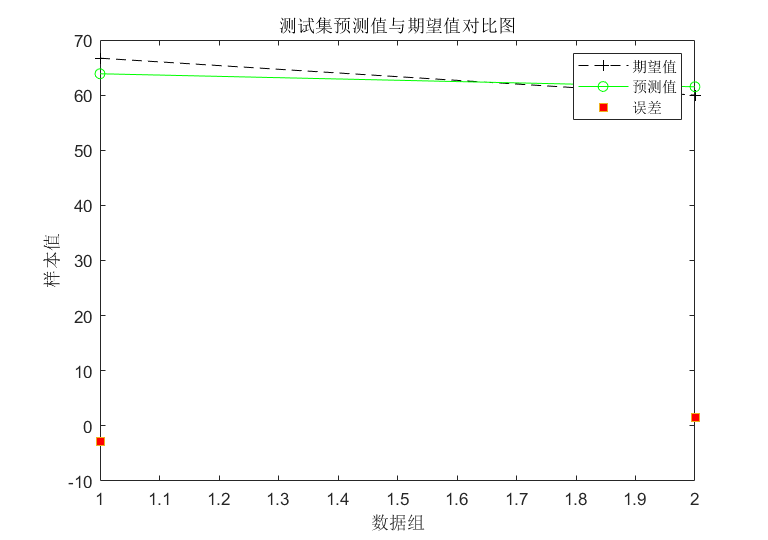

figure('units','normalized','Position',[0.10 0.20 0.40 0.50])
plot(output_test,'k+--');
hold on
plot(simulation_test,'go-')
hold on
plot(simulation_test-output_test,'square',"MarkerFaceColor",'r')
legend("期望值","预测值","误差")
xlabel('数据组')
ylabel('样本值')
title('测试集预测值与期望值对比图')

## 误差计算

error = simulation_test - output_test;
length = size(output_test,2);
MSE1 = error*error' / length;
MAE1 = sum(abs(error)) / length;
RMSE1 = sqrt(MSE1);
MAPE1 = 100 * sum((abs(error))/output_test) / length;

## 显示误差

disp('-----------------------误差计算--------------------------')

-----------------------误差计算--------------------------


disp(['输入层结点数为',num2str(input_number)])

输入层结点数为4


disp(['隐藏层结点数为',num2str(hidden_number)])

隐藏层结点数为5


disp(['输出层结点数为',num2str(output_number)])

输出层结点数为1


disp('误差结果如下：')

误差结果如下：



disp(['均方误误差MSE为： ',num2str(MSE1)])

均方误误差MSE为： 5.1403


disp(['平均绝对误差MAE为： ',num2str(MAE1)])

平均绝对误差MAE为： 2.1705


disp(['均方根误差RMSE为： ',num2str(RMSE1)])

均方根误差RMSE为： 2.2672


disp(['平均绝对百分比误差MAPE为： ',num2str(MAPE1), '%'])

平均绝对百分比误差MAPE为： 1.7356%
